heightmap=read(Tiff('C:\Users\jklebes001\Downloads\expk_0245\h_map\img_0001.tif','r'));
%just a tile
heightmap=heightmap(end-280:end-100, 5000:5180);

add stage scan heightmap

Input some additional information here:

lengthunit_name = "pixel" %for example, "nm"

lengthunit_name = "pixel"

voxel_size_x = .65/sqrt(2); 
voxel_size_y = .65;
voxel_size_z = .65*4/sqrt(2); %in chosen length unit

tile_size= 180;

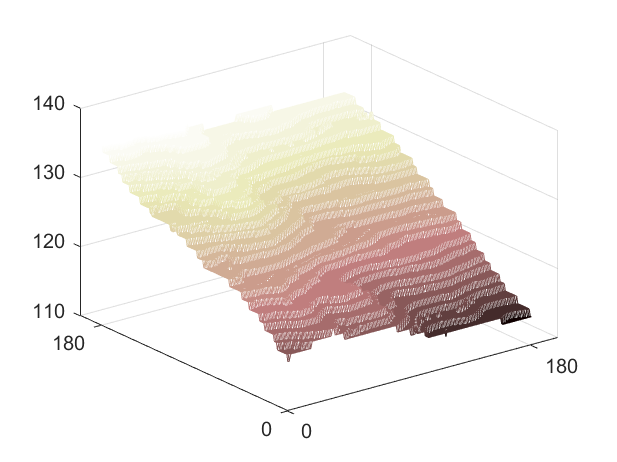

figure
mesh(heightmap);
%zlim([60, 140]);
shading interp;
colormap(pink);
ax=gca;
ax.YTick = 0:tile_size:2560;
ax.XTick = 0:tile_size:7951;

Analysis for metric (first fundamental form) and metric determinant

Try smoothin heightmap first.  Cell scale = 10 to 30 pixels.

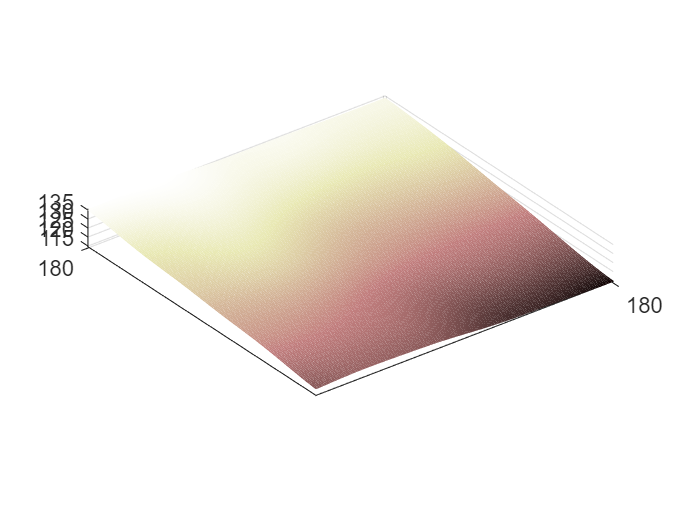

h_smooth = imgaussfilt(double(heightmap), 15);
figure
mesh(h_smooth);
zlim([60, 140]);
shading interp;
colormap(pink);
ax=gca;
ax.YTick = 0:tile_size:2560;
ax.XTick = 0:tile_size:7951;
axis equal

[diff_x, diff_y] = gradient(double(h_smooth)); %central difference
gxx =  1+diff_x.^2;
gyy =  1+diff_y.^2;
gxy= diff_x.*diff_y;
sqrtg = sqrt(gxx.*gyy - gxy.^2);

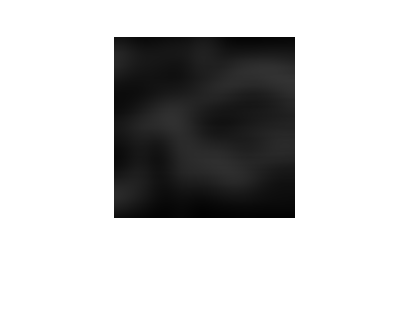

imshow(sqrtg,[1,1.05]);

%need second derivatives
%applying the second derivative opreator del2 rowwise/columnwise
del2x = splitapply(@(x) del2(x), h_smooth, 1:size(h_smooth,2));
del2y= splitapply(@(x) del2(x), h_smooth', 1:size(h_smooth,1));
del2y=del2y';
[crossdel,~] = gradient(diff_x);
%checked: del2x+del2y = del2(h_smooth)
factor = 1./sqrt(1+diff_x.^2+diff_y.^2)

factor =     0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9965    0.9965    0.9965    0.9966    0.9967    0.9968    0.9969    0.9969    0.9970    0.9971    0.9972    0.9973    0.9974    0.9975    0.9976    0.9977    0.9977    0.9978    0.9979    0.9980    0.9980    0.9980    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9980    0.9980    0.9980    0.9979    0.9979    0.9979    0.9978    0.9978    0.9978    0.9977    0.9977    0.9977    0.9977    0.9976
    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9964    0.9964    0.9964    0.9965    0.9966    0.9967    0.9968    0.9969    0.9969    0.9970    0.9971    0.9972    0.9973    0.9974    0.9975    0.9976    0.9977    0.9977    0.9978    0.9979    0.9979    0.9980    0.9980    0.9980    0.9980    0.9980    0.9980    0.9980    0.9980    0.9980    0.9979    0.9979    0.9979    0.9978    0.9978    0.9978    0.9977    0.9977    0.9977    0.9976    0.9976    0.9976

Gaussian_curvature = (del2x.*del2y+crossdel).*factor.^2;
mean_curvature = ((1+diff_x.^2).*del2y+(1+diff_y.^2).*del2x- ...
    -2.*diff_x.*diff_y.*crossdel)*0.5.*factor.^2;

Fit planes for each tile

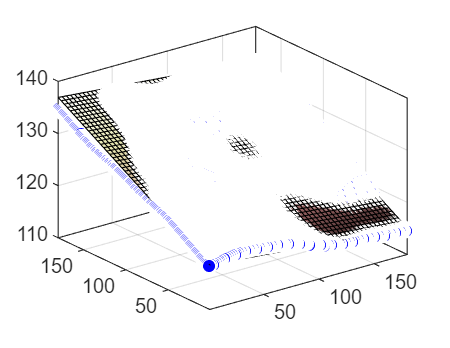

% a plane can be defined by a point and two linearly independed vectors
%point - center of fitted plane, average height of datapoint - but not
%necessary
% vectors - slope of linear fit in x, y directions
tile_start_x = 1;
tile_start_y = 1;
heights_tile = h_smooth(tile_start_x:tile_start_x+tile_size-1,tile_start_x:tile_start_x+tile_size-1);

%as 1D lists of coordinates
xs = reshape(repmat(tile_start_x:tile_start_x+tile_size-1, tile_size,1),[],1);
ys = reshape(repmat((tile_start_y:tile_start_y+tile_size-1)', 1, tile_size),[],1);
zs = reshape(heights_tile,[], 1);

planefit = fit([xs,ys], zs, 'poly11');
plot(planefit, [xs,ys],zs);

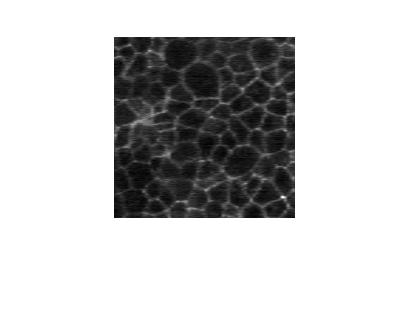

%see data in this plane
img=read(Tiff('C:\Users\jklebes001\Downloads\expk_0245\merged\img_0001.tif','r'));
data=img(end-280:end-100, 5000:5180);
imshow(data,[]);

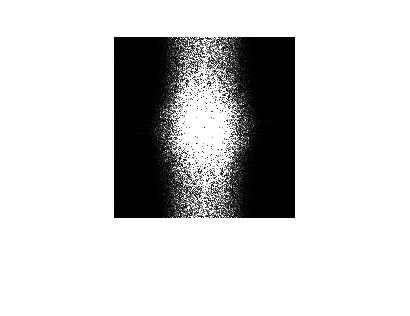

%anisotropy calculation on the data as-is
addpath('../myosin-cable-detection/FTgui/');
[FT] = fft_adir(data);
%[FT] = fft_adir(imgaussfilt(data,1.5));
FT2 =  abs(fftshift(fftn(data))); %without perdecomp
imshow(FT,[0,100]) %prominent anisotropy

%probably not because of tilt of image? 
%stretching out this FT (in a reciprocal way)
%will not get rid of this anisotropy

%problem is not in 'perdecomp' decomposition

%there seems to be a very low-frequency y-direction pattern
%not an edge artefact

%interestingly imgaussfilt sigma >1 gets rid of the anisotropy

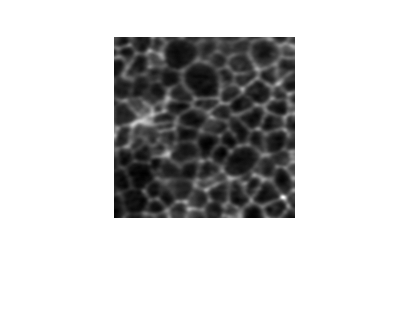

imshow(imgaussfilt(data,1.5),[])

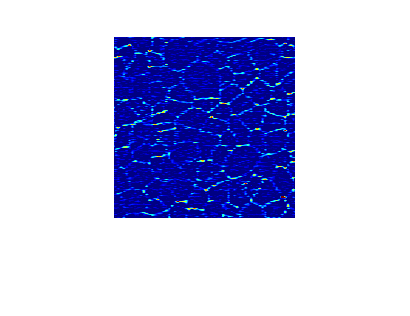

imshow(data-imgaussfilt(data,1.5),[0,50])
colormap jet

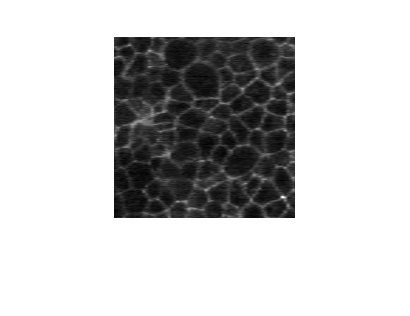

invFT = ifft2(fftshift(fftn(data)));
imshow(abs(invFT), [])

% matrix which streteches the gradient vector 
% (first eigenvector of desired transformation)
% by sqrt(1+grad^2)
p10 = planefit.p10;
p01 = planefit.p01; %numbers seem right for x y grad components
factor=sqrt(1+p10^2+p01^2); %not big,as expected
A=1/(p01^2+p10^2)*(p10^2*factor +p01^2);
B=1/(p01^2+p10^2)*(p10*p01*(factor-1)); %=C
D=1/(p01^2+p10^2)*(p01^2*factor +p10^2);
transform=[A,B;B,D]%mostly stretches along y axis in this case

transform =     1.0002   -0.0010
   -0.0010    1.0053


                    %but not by much